Import image

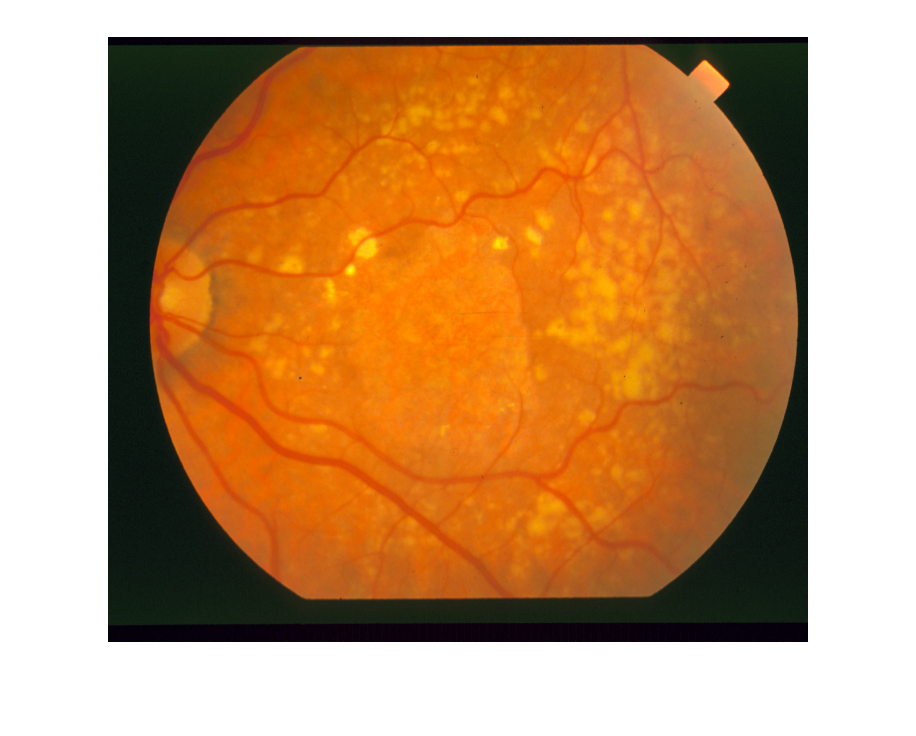

O = imread('../dataset/STARE/image/im0003.ppm');
imshow(O,[])

Green channel

G = double(O(:,:,2));

Background Estimation

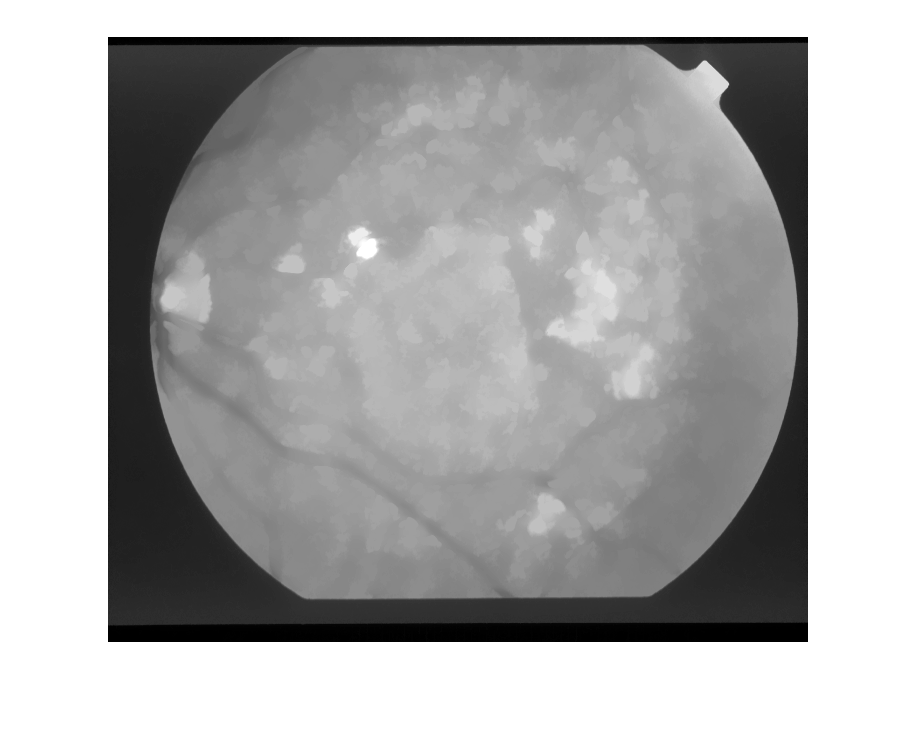

bgEst1 = medfilt2(G, [25 25]);

bgMask = zeros(size(G),'double');

for i = 1:numel(G)
    if (G(i) < bgEst1(i))
        bgMask(i) = bgEst1(i);
    else
        bgMask(i) = G(i);
    end
end

bgEst2 = imreconstruct(bgEst1, bgMask);

imshow(bgEst2,[]);

Image normalize

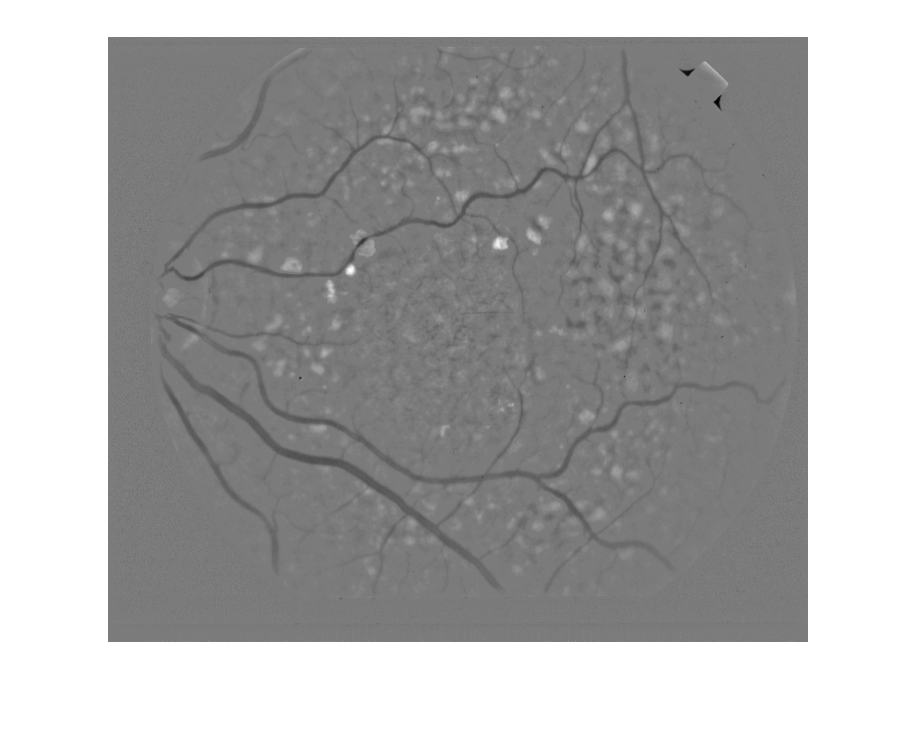

normalized = G - bgEst2;

imshow(normalized,[])

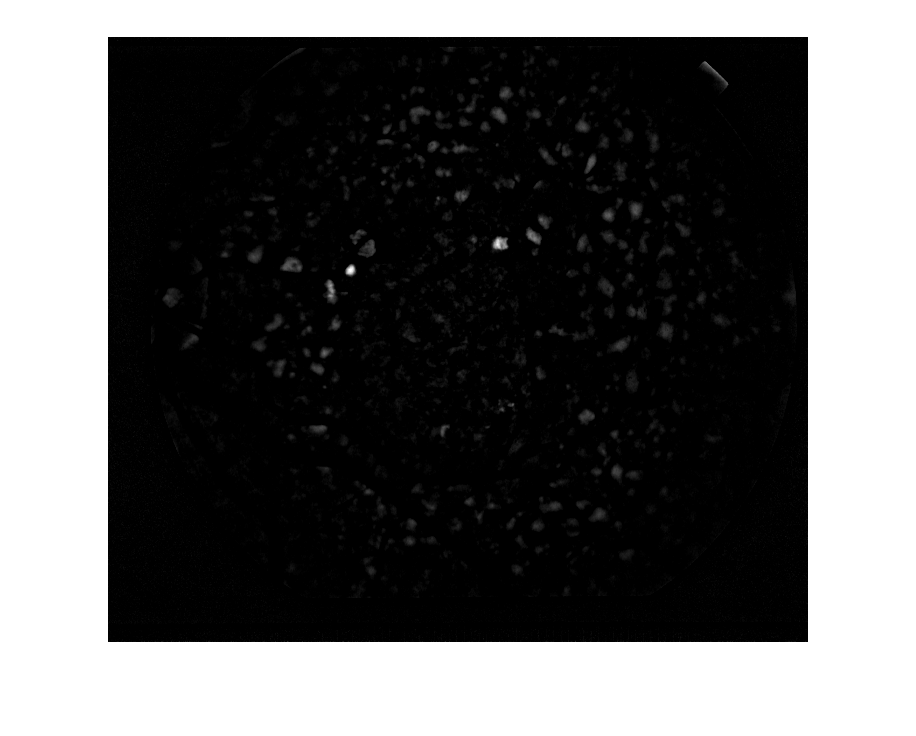


noves = normalized;
noves(normalized < 0) = 0;
noves = rescale(noves,0,255);
imshow(noves,[]);

Exudate candidate

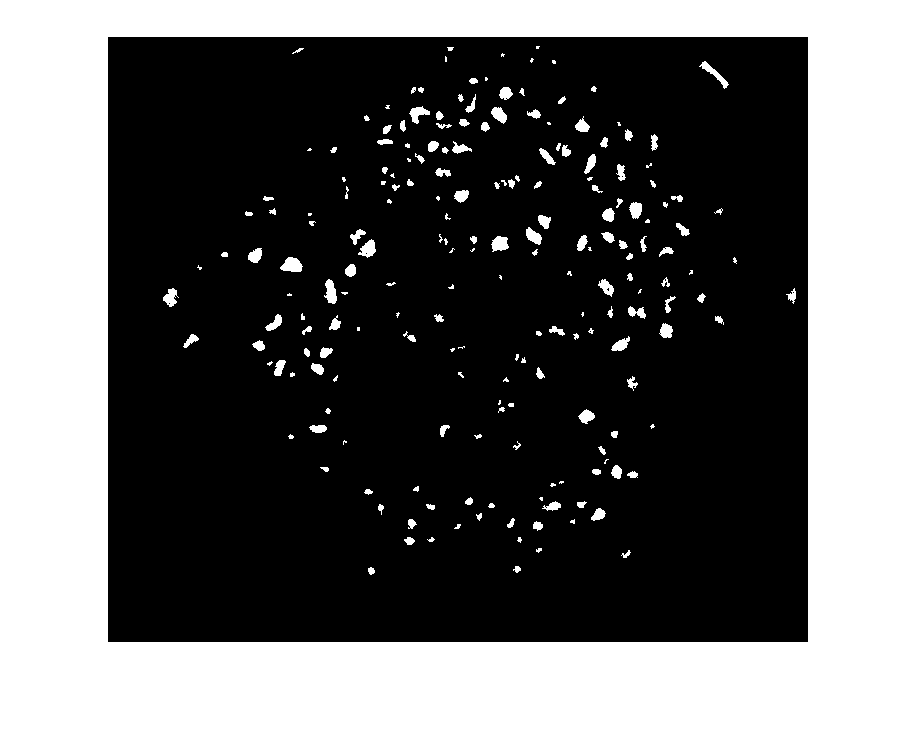

thres = normalized;
thres(normalized < 10) = 0;
thres(normalized >= 10) = 1;

thres = logical(thres);
thres = bwareafilt(thres,[10 Inf]);
imshow(thres,[])

Kirsch's kernels

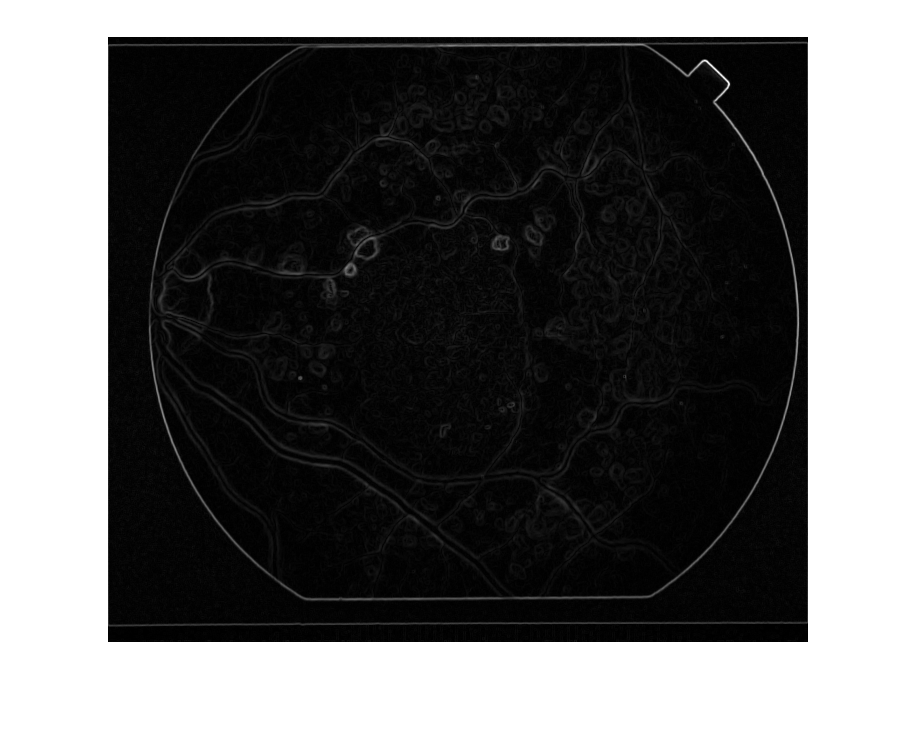

k(:,:,1) = [ 5, 5, 5;-3, 0,-3;-3,-3,-3]/15;
k(:,:,2) = [ 5, 5,-3; 5, 0,-3;-3,-3,-3]/15;
k(:,:,3) = [ 5,-3,-3; 5, 0,-3; 5,-3,-3]/15;
k(:,:,4) = [-3,-3,-3; 5, 0,-3; 5, 5,-3]/15;
k(:,:,5) = [-3,-3,-3;-3, 0,-3; 5, 5, 5]/15;
k(:,:,6) = [-3,-3,-3;-3, 0, 5;-3, 5, 5]/15;
k(:,:,7) = [-3,-3, 5;-3, 0, 5;-3,-3, 5]/15;
k(:,:,8) = [-3, 5, 5;-3, 0, 5;-3,-3,-3]/15;


c = zeros([size(G),8],'double');

for i = 1:8 
    c(:,:,i) = conv2(G,k(:,:,i),'same');
end


r = max(c,[],3);
% 
imshow(r,[]);

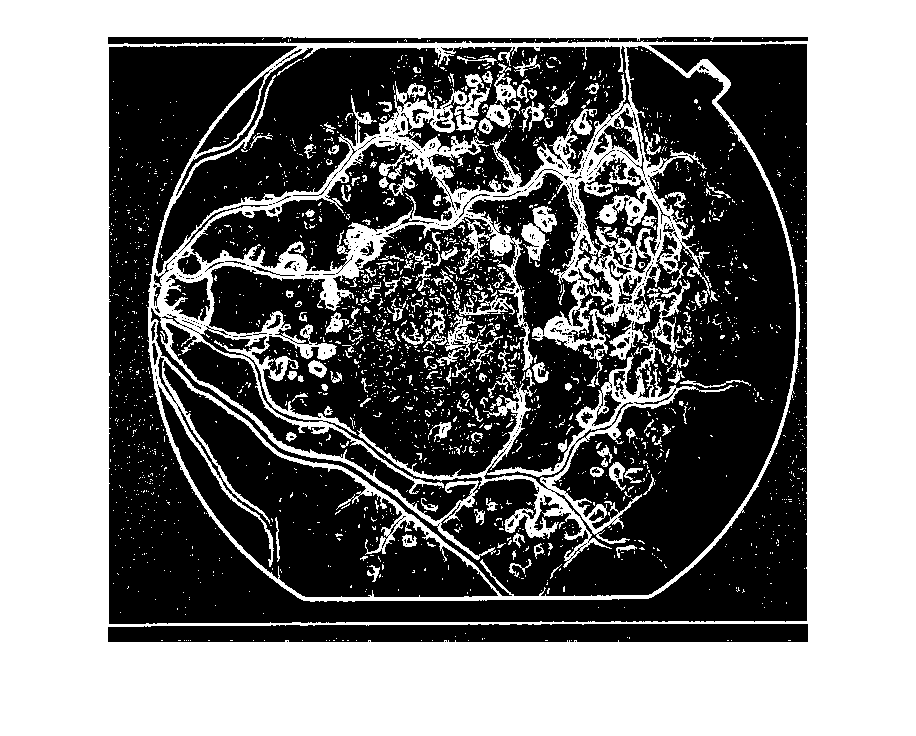


th = r;
th(r > 5)   =1;
th(r <= 5)  = 0;
th = logical(th);
imshow(th);

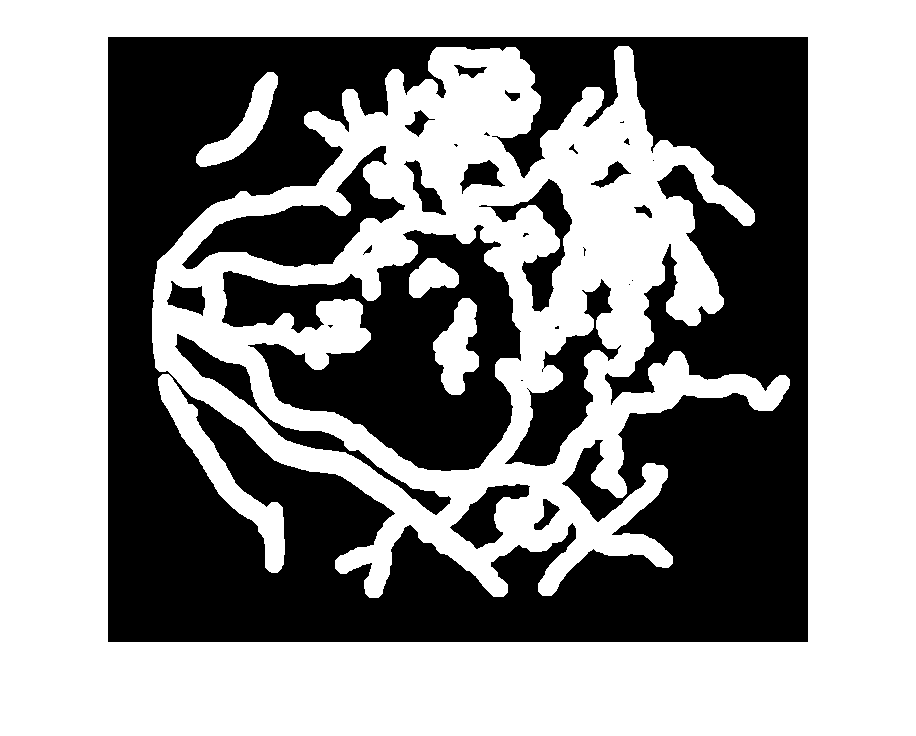


mask = get_mask(O);
vessel = get_vessel(O,mask);
vessel = imdilate(vessel,strel('disk',8));
imshow(vessel);

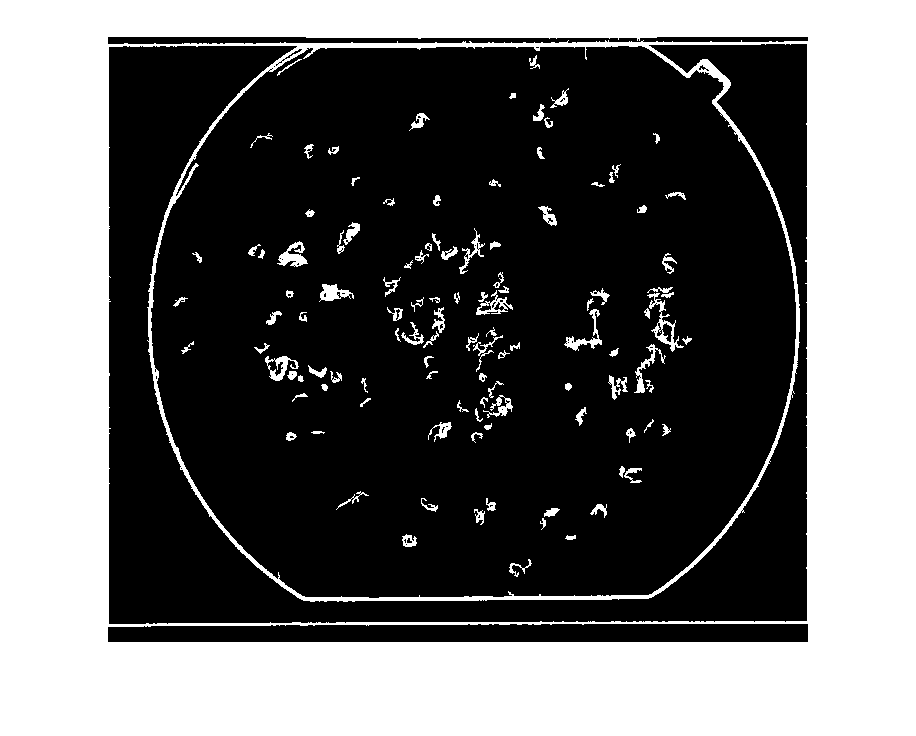


res = th-vessel;
res(res>0) = 1;
res(res <=0) = 0;
res = logical(res);
res = bwareafilt(res,[30 Inf]);
imshow(res);

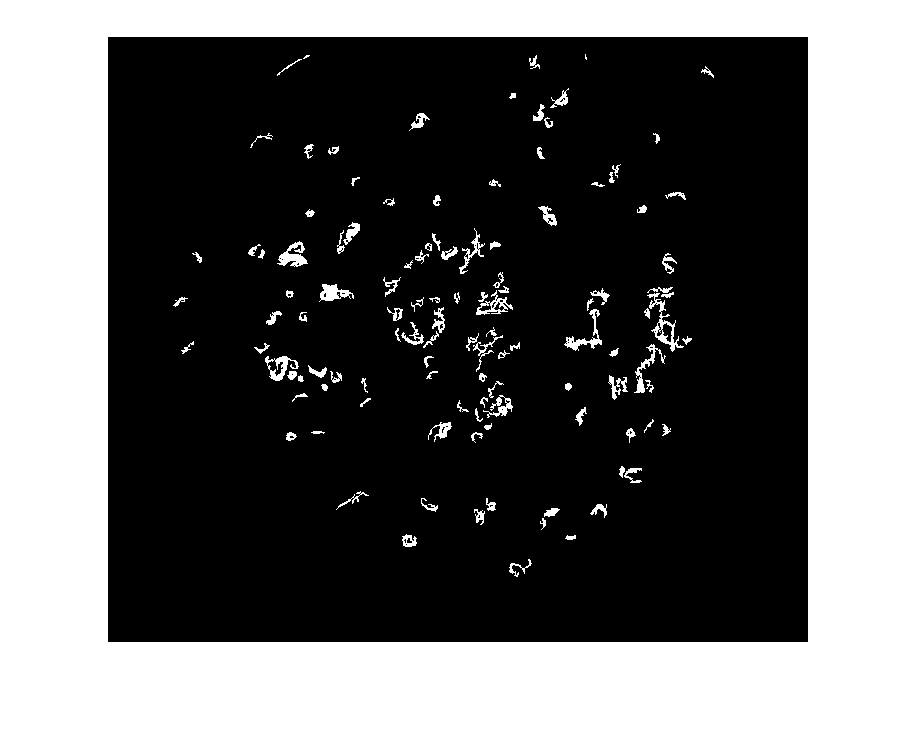


test = bitand(mask,res);
imshow(test);

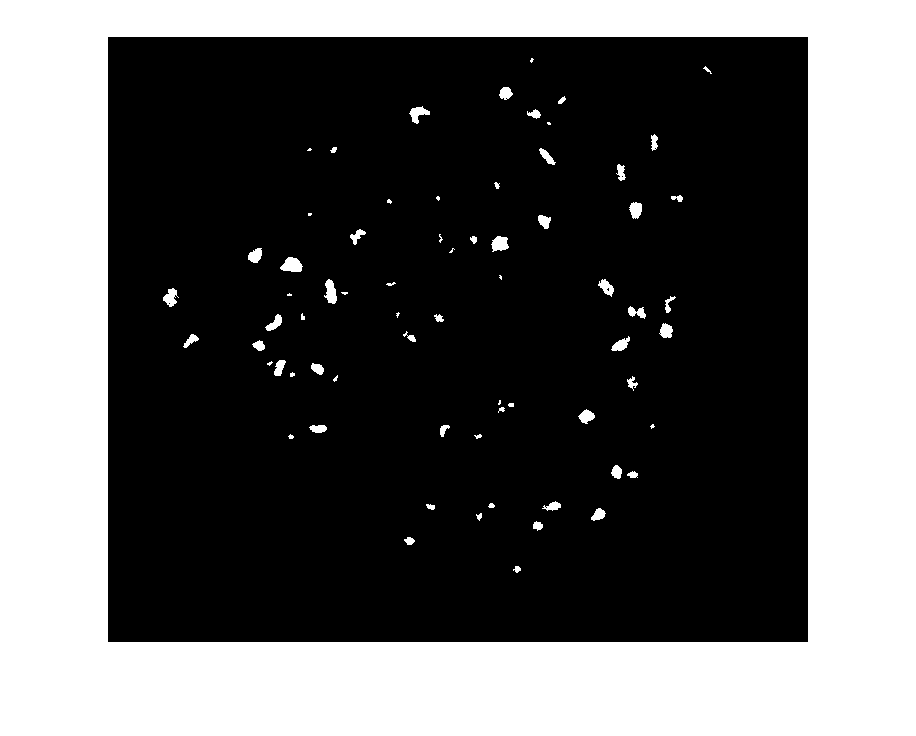


recon = imreconstruct(test,thres);
recon = bitand(recon,mask);
imshow(recon);


num_exu = 0;
for n = 1:numel(recon)
    if (recon(n) == 1)
        num_exu = num_exu + 1;
    end
end
num_exu

num_exu = 5044

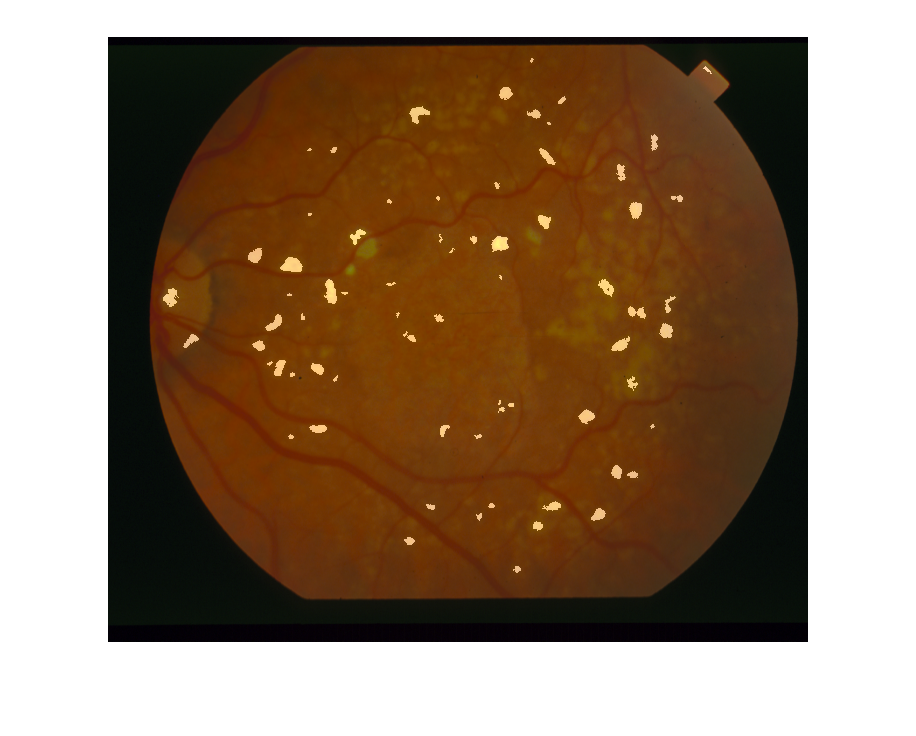


imshowpair(recon, O, 'blend')